# Transfer Learn from GoogLeNet

## Load Training Data

load ../data/ColorCast/trainingData.mat
trainds = augmentedImageDatastore([224 224], trainingData);

## Define Network Architecture

net = googlenet;
layers = layerGraph(net);
newfc = fullyConnectedLayer(3);
newvalue = regressionLayer;

layers = replaceLayer(layers, layers.Layers(end-2).Name, newfc);
layers = replaceLayer(layers, layers.Layers(end).Name, newvalue);
layers = removeLayers(layers, layers.Layers(end-1).Name);
layers = connectLayers(layers, layers.Layers(end-1).Name, layers.Layers(end).Name);

options = trainingOptions(  "adam", ...
                            "MiniBatchSize", 32, ...
                            "InitialLearnRate", 0.0001, ...
                            "MaxEpochs", 10, ...
                            "Shuffle", "every-epoch", ...
                            "Verbose", true, ...
                            "Plots", "training-progress");

## Train the network

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |        40.13 |        805.1 |      1.0000e-04 |
|       1 |          50 |       00:00:27 |        25.47 |        324.4 |      1.0000e-04 |
|       2 |         100 |       00:00:51 |        12.74 |         81.1 |      1.0000e-04 |
|       3 |         150 |       00:01:15 |        11.56 |         66.8 |      1.0000e-04 |
|       4 |         200 |       00:01:41 |         7.52 |         28.3 |      1.0000e-04 |
|       4 |         250 |       00:02:02 |         7.02 |         24.6 |      1.0000e-04 |
|       5 |         300 |  

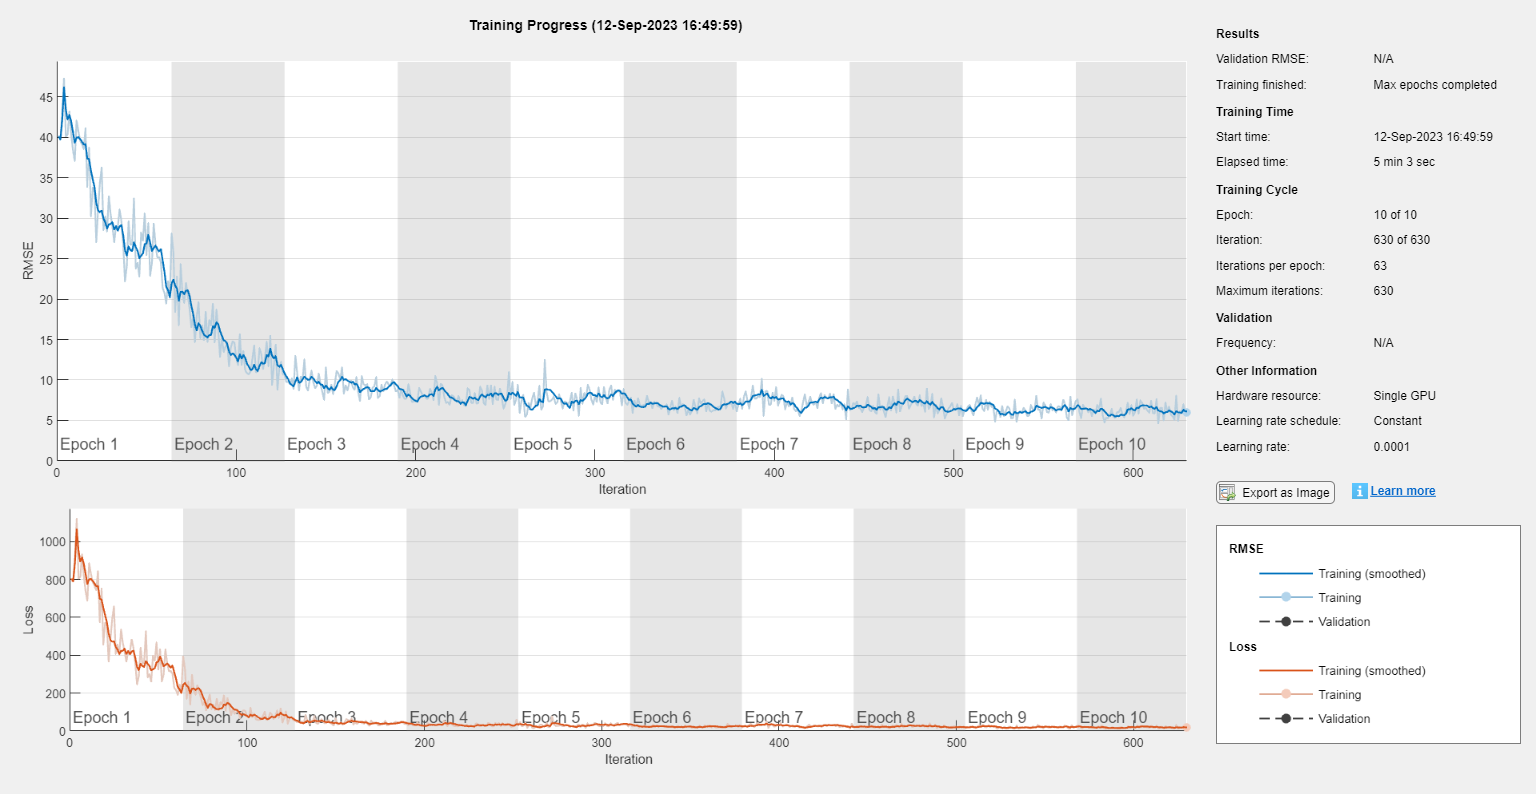

net = trainNetwork(trainds, layers, options);